## Interta matrix using DH generalized coordinate

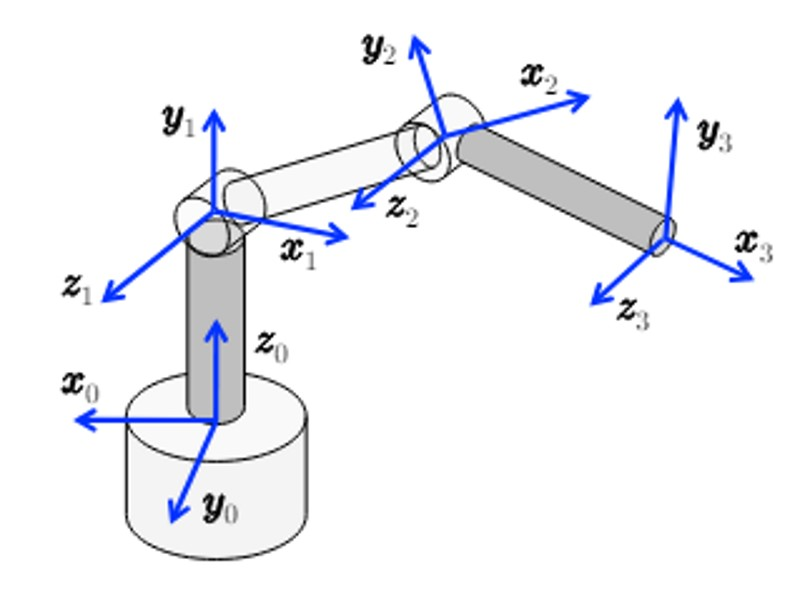

syms alpha d d1 d2 d4 d6 a a1 a2 a3 a4 theta q1 q2 q3 q4 q5 q6
syms l1 l2 l3

%% number of joints 
N=3;


%% PAY ATTENTION TO THE POSITION OF
%% a and d: a is the second column
%% d the third!

DHTABLE = [  pi/2   l1   0    q1;
               0    0   l2    q2;
               0    0   l3    q3];

         
TDH = [ cos(theta) -sin(theta)*cos(alpha)  sin(theta)*sin(alpha) a*cos(theta);
        sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
          0             sin(alpha)             cos(alpha)            d;
          0               0                      0                   1];

A = cell(1,N);

for i = 1:N 
    alpha = DHTABLE(i,1);
    a = DHTABLE(i,2);
    d = DHTABLE(i,3);
    theta = DHTABLE(i,4);
    A{i} = subs(TDH);
    disp(i)
    disp(A{i})
end

     1



$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & l_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & l_{1}\,\sin\left(q_{1}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

     2



$$\left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & 0\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

     3



$$\left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & 0\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$



T = eye(4);

for i=1:N 
    T = T*A{i};
    T = simplify(T);
end

T0N = T;

p = T(1:3,4);

n = T(1:3,1);

s = T(1:3,2);

a = T(1:3,3);

A_0_1 = A{1};

A_0_2 = A{1} * A{2};

A_0_3 = simplify(A{1} * A{2} * A{3},steps=100);

p_01 = A_0_1(1:3, end);
p_02 = A_0_2(1:3, end);
p_03 = A_0_3(1:3, end);

p_0_E = p_03;
p_1_E = p_03 - p_01;
p_2_E = p_03 - p_02;
p_3_E = p_03 - p_03;

R_0_1 = A_0_1(1:3, 1:3)

$$R\_0\_1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right)\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right)\\ 0 & 1 & 0 \end{array}\right)$$

R_0_2 = A_0_2(1:3, 1:3)

$$R\_0\_2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{1}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 \end{array}\right)$$

R_1_2 = simplify(R_0_1.'*R_0_2, steps=100)

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_0_3 = A_0_3(1:3, 1:3)

$$R\_0\_3 = \left(\begin{array}{ccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right)\\ \sin\left(q_{2}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & 0 \end{array}\right)$$

R_2_3 = simplify(R_1_2.'*R_0_1.'*R_0_3, steps=100)

$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


z_0 = [0;
       0;
       1];

z_1 = simplify(R_0_1*z_0, Steps=100);
z_2 = simplify(R_0_2*z_0, Steps=100);

p_z_0 = simplify(cross(z_0, p_0_E), steps = 100);
p_z_1 = simplify(cross(z_1, p_1_E), steps = 100);
p_z_2 = simplify(cross(z_2, p_2_E), steps = 100);

## Moving frames Algorithms

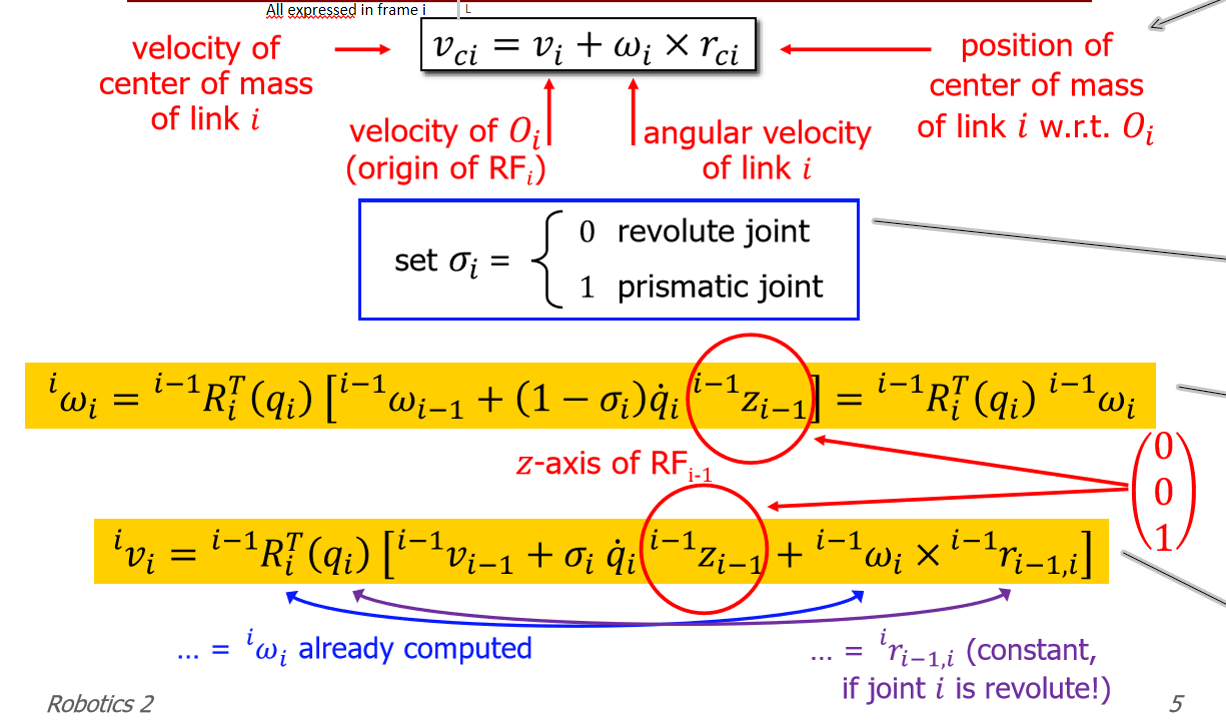

syms dq1 dq2 dq3 m1 m2 m3 positive
syms A E F C D I1 I2 I3 positive
syms I1_xx I1_yy I1_zz I2_xx I2_yy I2_zz I3_xx I3_yy I3_zz positive

% Link 1
w_1_1 = R_0_1.'*[0; 0; dq1;];
v_1_c1 = [0; 0; -A*dq1;];
T1_tr = 0.5*m1*(simplify((norm(v_1_c1)^2), steps=100))

$$T1\_tr = \frac{A^{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}$$

T1_rot = 0.5*(I1 + m1*A^2)*dq1^2

$$T1\_rot = {{\mathrm{dq}}_{1}}^{2}\,\left(\frac{m_{1}\,A^{2}}{2}+\frac{I_{1}}{2}\right)$$

T1 = T1_tr+T1_rot;

% Link 2
w_2_2 = R_1_2.'*[0; dq1; dq2;];
w_1_2 = simplify(R_1_2*w_2_2, steps=100);
v_2_2 = (cross(w_2_2,[l2; 0; 0;]))

$$v\_2\_2 = \left(\begin{array}{c} 0\\ {\mathrm{dq}}_{2}\,l_{2}\\ -{\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

v_2_c2 = v_2_2 + cross(w_2_2,[-C; 0; 0;])

$$v\_2\_c2 = \left(\begin{array}{c} 0\\ {\mathrm{dq}}_{2}\,l_{2}-C\,{\mathrm{dq}}_{2}\\ C\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

T2_tr = 0.5*m1*(simplify((norm(v_2_c2)^2), steps=100))

$$T2\_tr = \frac{m_{1}\,{\left|C-l_{2}\right|}^{2}\,\left({{\mathrm{dq}}_{1}}^{2}\,{\left|\cos\left(q_{2}\right)\right|}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}$$

T2_rot = 0.5*(I2 + m2*(l2-C)^2)*norm(w_2_2)^2

$$T2\_rot = \left(\frac{I_{2}}{2}+\frac{m_{2}\,{\left(C-l_{2}\right)}^{2}}{2}\right)\,\left({{\mathrm{dq}}_{1}}^{2}\,{\left|\cos\left(q_{2}\right)\right|}^{2}+{{\mathrm{dq}}_{1}}^{2}\,{\left|\sin\left(q_{2}\right)\right|}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)$$

T2 = T2_tr+T2_rot;

% Link 3
w_3_3 = R_2_3.'*(w_2_2+[0;0;dq3])

$$w\_3\_3 = \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+{\mathrm{dq}}_{1}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-{\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ {\mathrm{dq}}_{2}+{\mathrm{dq}}_{3} \end{array}\right)$$

v_3_3 = R_2_3.'*(v_2_2 + cross(w_3_3,[l3;0;0;]))

$$v\_3\_3 = \left(\begin{array}{c} \sin\left(q_{3}\right)\,\left({\mathrm{dq}}_{2}\,l_{2}+l_{3}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)\right)\\ \cos\left(q_{3}\right)\,\left({\mathrm{dq}}_{2}\,l_{2}+l_{3}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)\right)\\ -l_{3}\,\left({\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-{\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)-{\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

v_3_c3 = v_3_3 + cross(w_3_3,[-D;0;E])

$$v\_3\_c3 = \begin{array}{l} \left(\begin{array}{c} \sin\left(q_{3}\right)\,\left({\mathrm{dq}}_{2}\,l_{2}+l_{3}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)\right)+\text{E}\,\sigma_{1}\\ \cos\left(q_{3}\right)\,\left({\mathrm{dq}}_{2}\,l_{2}+l_{3}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)\right)-\text{D}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)-\text{E}\,\left({\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+{\mathrm{dq}}_{1}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)\\ \text{D}\,\sigma_{1}-l_{3}\,\sigma_{1}-{\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-{\mathrm{dq}}_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) \end{array}$$


T3_tr = 0.5*m3*(simplify((norm(v_3_c3)^2),Steps=100))

$$T3\_tr = \begin{array}{l} \frac{m_{3}\,\left({\left|\text{D}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)-\cos\left(q_{3}\right)\,\sigma_{1}+\text{E}\,{\mathrm{dq}}_{1}\,\sin\left(q_{2}+q_{3}\right)\right|}^{2}+{\left|\sin\left(q_{3}\right)\,\sigma_{1}+\text{E}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right)\right|}^{2}+{\left|{\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{2}\right)-\text{D}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right)+{\mathrm{dq}}_{1}\,l_{3}\,\cos\left(q_{2}+q_{3}\right)\right|}^{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{2}\,l_{2}+l_{3}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right) \end{array}$$

T3_rot = 0.5*(I3 + m2*(l2-C)^2)*norm(w_2_2)^2

$$T3\_rot = \left(\frac{I_{3}}{2}+\frac{m_{2}\,{\left(C-l_{2}\right)}^{2}}{2}\right)\,\left({{\mathrm{dq}}_{1}}^{2}\,{\left|\cos\left(q_{2}\right)\right|}^{2}+{{\mathrm{dq}}_{1}}^{2}\,{\left|\sin\left(q_{2}\right)\right|}^{2}+{{\mathrm{dq}}_{2}}^{2}\right)$$

T3 = T3_tr+T3_rot;

% Total Kinetic
T = T1+T2+T3

$$T = \begin{array}{l} {{\mathrm{dq}}_{1}}^{2}\,\left(\frac{m_{1}\,A^{2}}{2}+\frac{I_{1}}{2}\right)+\left(\frac{I_{2}}{2}+\sigma_{2}\right)\,\sigma_{3}+\left(\frac{I_{3}}{2}+\sigma_{2}\right)\,\sigma_{3}+\frac{m_{3}\,\left({\left|\text{D}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)-\cos\left(q_{3}\right)\,\sigma_{1}+\text{E}\,{\mathrm{dq}}_{1}\,\sin\left(q_{2}+q_{3}\right)\right|}^{2}+{\left|\sin\left(q_{3}\right)\,\sigma_{1}+\text{E}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right)\right|}^{2}+{\left|{\mathrm{dq}}_{1}\,l_{2}\,\cos\left(q_{2}\right)-\text{D}\,{\mathrm{dq}}_{1}\,\cos\left(q_{2}+q_{3}\right)+{\mathrm{dq}}_{1}\,l_{3}\,\cos\left(q_{2}+q_{3}\right)\right|}^{2}\right)}{2}+\frac{A^{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}+\frac{m_{1}\,{\left|C-l_{2}\right|}^{2}\,\left(\sigma_{4}+{{\mathrm{dq}}_{2}}^{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dq}}_{2}\,l_{2}+l_{3}\,\left({\mathrm{dq}}_{2}+{\mathrm{dq}}_{3}\right)\\ \sigma_{2}=\frac{m_{2}\,{\left(C-l_{2}\right)}^{2}}{2}\\ \sigma_{3}=\sigma_{4}+{{\mathrm{dq}}_{1}}^{2}\,{\left|\sin\left(q_{2}\right)\right|}^{2}+{{\mathrm{dq}}_{2}}^{2}\\ \sigma_{4}={{\mathrm{dq}}_{1}}^{2}\,{\left|\cos\left(q_{2}\right)\right|}^{2} \end{array}$$


disp('=============================================')

disp('Code from Git')

Code from Git


disp('=============================================')


% Inertia Matrix
% M11 = diff(diff(T, dq1), dq1);
% M12 = diff(diff(T, dq1), dq2);
% M13 = diff(diff(T, dq1), dq3);
% 
% M21 = M12;
% M22 = diff(diff(T, dq2), dq2);
% M23 = diff(diff(T, dq2), dq3);
% 
% M31 = M13;
% M32 = M23;
% M33 = diff(diff(T, dq3), dq3);
% 
% M = [M11, M12, M13;
%      M21, M22, M23;
%      M31, M32, M33];
% 
% M = simplify(M);
% 
% disp('The inertia matrix M(q) is:');
% disp(M);

## Git Hub code

syms q1 q2 q3 real
syms qd1 qd2 qd3 real
syms L1 L2 L3 A C D E F real
syms m1 m2 m3 real
syms Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 real

% Numero di giunti
n = 3;

% DH table: [alpha, a, d, theta]
DH = [
    pi/2, 0,  L1, q1;
    0,    L2, 0,  q2;
    0,    L3, 0,  q3
];

% Vettore delle velocità articolari
qdots = [qd1; qd2; qd3];

% Masse
m = [m1; m2; m3];

% Vettori dei baricentri nei frame locali
rc = [ A, -C, -D;
      -F,  0,   0;
       0,  0,   E];

% Indici dei giunti prismatici (vuoto perché tutti rotazionali)
prismatic_indices = [];

% Matrici d'inerzia baricentriche per ogni link (concatenate)
I = [...
    Ixx1, 0,    0,    Iyy1, 0,    0,    Izz1, 0,    0;
    0,    Ixx2, 0,    0,    Iyy2, 0,    0,    Izz2, 0;
    0,    0,    Ixx3, 0,    0,    Iyy3, 0,    0,    Izz3];

% Call della funzione principale
[w, v, vc, T] = moving_frames_algorithm(n, DH, qdots, m, rc, prismatic_indices, I);

---- Starting the Moving Frames Algorithm ----
Number of joints: 3
The value of w_1 is:


$$\left(\begin{array}{c} 0\\ {\mathrm{qd}}_{1}\\ 0 \end{array}\right)$$

The value of v_1 is:


$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

The value of vc_1 is:


$$\left(\begin{array}{c} 0\\ 0\\ -A\,{\mathrm{qd}}_{1} \end{array}\right)$$

The value of T_1 is:


$$\frac{{{\mathrm{qd}}_{1}}^{2}\,\left(m_{1}\,A^{2}+{\mathrm{Ixx}}_{2}\right)}{2}$$

The value of w_2 is:


$$\left(\begin{array}{c} {\mathrm{qd}}_{1}\,\sin\left(q_{2}\right)\\ {\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\\ {\mathrm{qd}}_{2} \end{array}\right)$$

The value of v_2 is:


$$\left(\begin{array}{c} 0\\ {\mathrm{qd}}_{2}\,\left(L_{2}\,{\cos\left(q_{2}\right)}^{2}+L_{2}\,{\sin\left(q_{2}\right)}^{2}\right)\\ -{\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\left(L_{2}\,{\cos\left(q_{2}\right)}^{2}+L_{2}\,{\sin\left(q_{2}\right)}^{2}\right) \end{array}\right)$$

The value of vc_2 is:


$$\left(\begin{array}{c} 0\\ {\mathrm{qd}}_{2}\,\left(L_{2}\,{\cos\left(q_{2}\right)}^{2}+L_{2}\,{\sin\left(q_{2}\right)}^{2}\right)-C\,{\mathrm{qd}}_{2}\\ C\,{\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)-{\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\left(L_{2}\,{\cos\left(q_{2}\right)}^{2}+L_{2}\,{\sin\left(q_{2}\right)}^{2}\right) \end{array}\right)$$

The value of T_2 is:


$$\frac{{\mathrm{Iyy}}_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{2}\,{\left(C-L_{2}\right)}^{2}\,\left({{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{qd}}_{2}}^{2}\right)}{2}+\frac{{\mathrm{Iyy}}_{2}\,{{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{\mathrm{Iyy}}_{1}\,{{\mathrm{qd}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}$$

The value of w_3 is:


$$\left(\begin{array}{c} {\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+{\mathrm{qd}}_{1}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ {\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-{\mathrm{qd}}_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ {\mathrm{qd}}_{2}+{\mathrm{qd}}_{3} \end{array}\right)$$

The value of v_3 is:


$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{qd}}_{2}\,\sin\left(q_{3}\right)\,\sigma_{1}\\ \left(L_{3}\,{\cos\left(q_{3}\right)}^{2}+L_{3}\,{\sin\left(q_{3}\right)}^{2}\right)\,\left({\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)+{\mathrm{qd}}_{2}\,\cos\left(q_{3}\right)\,\sigma_{1}\\ -\left(L_{3}\,{\cos\left(q_{3}\right)}^{2}+L_{3}\,{\sin\left(q_{3}\right)}^{2}\right)\,\left({\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-{\mathrm{qd}}_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)-{\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,{\cos\left(q_{2}\right)}^{2}+L_{2}\,{\sin\left(q_{2}\right)}^{2} \end{array}$$

The value of vc_3 is:


$$\begin{array}{l} \left(\begin{array}{c} \text{E}\,\sigma_{1}+{\mathrm{qd}}_{2}\,\sin\left(q_{3}\right)\,\sigma_{2}\\ \sigma_{3}\,\left({\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)-\text{E}\,\left({\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+{\mathrm{qd}}_{1}\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)-\text{D}\,\left({\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)+{\mathrm{qd}}_{2}\,\cos\left(q_{3}\right)\,\sigma_{2}\\ \text{D}\,\sigma_{1}-\sigma_{3}\,\sigma_{1}-{\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{qd}}_{1}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-{\mathrm{qd}}_{1}\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{2}=L_{2}\,{\cos\left(q_{2}\right)}^{2}+L_{2}\,{\sin\left(q_{2}\right)}^{2}\\ \sigma_{3}=L_{3}\,{\cos\left(q_{3}\right)}^{2}+L_{3}\,{\sin\left(q_{3}\right)}^{2} \end{array}$$

The value of T_3 is:


$$\frac{m_{3}\,\left({{\mathrm{qd}}_{1}}^{2}\,{\left(L_{3}\,\cos\left(q_{2}+q_{3}\right)-\text{D}\,\cos\left(q_{2}+q_{3}\right)+L_{2}\,\cos\left(q_{2}\right)\right)}^{2}+{\left(L_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{3}\right)+\text{E}\,{\mathrm{qd}}_{1}\,\cos\left(q_{2}+q_{3}\right)\right)}^{2}+{\left(\text{D}\,{\mathrm{qd}}_{2}+\text{D}\,{\mathrm{qd}}_{3}-L_{3}\,{\mathrm{qd}}_{2}-L_{3}\,{\mathrm{qd}}_{3}+\text{E}\,{\mathrm{qd}}_{1}\,\sin\left(q_{2}+q_{3}\right)-L_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{3}\right)\right)}^{2}\right)}{2}+\frac{{\mathrm{Izz}}_{2}\,{{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}+q_{3}\right)}^{2}}{2}+\frac{{\mathrm{Izz}}_{1}\,{{\mathrm{qd}}_{1}}^{2}\,{\sin\left(q_{2}+q_{3}\right)}^{2}}{2}+{\mathrm{Izz}}_{3}\,\left(\frac{{\mathrm{qd}}_{2}}{2}+\frac{{\mathrm{qd}}_{3}}{2}\right)\,\left({\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)$$


% Energia cinetica totale
T_total = simplify(T{1} + T{2} + T{3});
disp("Energia cinetica totale T = 1/2 * qd' * B(q) * qd:");

Energia cinetica totale T = 1/2 * qd' * B(q) * qd:


disp(T_total);

$$\frac{{{\mathrm{qd}}_{1}}^{2}\,\left(m_{1}\,A^{2}+{\mathrm{Ixx}}_{2}\right)}{2}+\frac{{\mathrm{Iyy}}_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,\left({{\mathrm{qd}}_{1}}^{2}\,{\left(L_{3}\,\cos\left(q_{2}+q_{3}\right)-\text{D}\,\cos\left(q_{2}+q_{3}\right)+L_{2}\,\cos\left(q_{2}\right)\right)}^{2}+{\left(L_{2}\,{\mathrm{qd}}_{2}\,\sin\left(q_{3}\right)+\text{E}\,{\mathrm{qd}}_{1}\,\cos\left(q_{2}+q_{3}\right)\right)}^{2}+{\left(\text{D}\,{\mathrm{qd}}_{2}+\text{D}\,{\mathrm{qd}}_{3}-L_{3}\,{\mathrm{qd}}_{2}-L_{3}\,{\mathrm{qd}}_{3}+\text{E}\,{\mathrm{qd}}_{1}\,\sin\left(q_{2}+q_{3}\right)-L_{2}\,{\mathrm{qd}}_{2}\,\cos\left(q_{3}\right)\right)}^{2}\right)}{2}+\frac{m_{2}\,{\left(C-L_{2}\right)}^{2}\,\left({{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{qd}}_{2}}^{2}\right)}{2}+\frac{{\mathrm{Izz}}_{2}\,{{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}+q_{3}\right)}^{2}}{2}+\frac{{\mathrm{Izz}}_{1}\,{{\mathrm{qd}}_{1}}^{2}\,{\sin\left(q_{2}+q_{3}\right)}^{2}}{2}+\frac{{\mathrm{Iyy}}_{2}\,{{\mathrm{qd}}_{1}}^{2}\,{\cos\left(q_{2}\right)}^{2}}{2}+\frac{{\mathrm{Iyy}}_{1}\,{{\mathrm{qd}}_{1}}^{2}\,{\sin\left(q_{2}\right)}^{2}}{2}+{\mathrm{Izz}}_{3}\,\left(\frac{{\mathrm{qd}}_{2}}{2}+\frac{{\mathrm{qd}}_{3}}{2}\right)\,\left({\mathrm{qd}}_{2}+{\mathrm{qd}}_{3}\right)$$


% Ricavare la matrice B(q)
qdot = [qd1; qd2; qd3];
B = jacobian(jacobian(T_total, qdot).', qdot);
disp("Matrice d'inerzia B(q):");

Matrice d'inerzia B(q):


pretty(simplify(B))

/                       2         2                                                     2                                                                                                                                                               \
|         2      m3 (2 E  #4 + 2 E  #3 + (L3 cos(q2 + q3) - D cos(q2 + q3) + L2 cos(q2))  2)                                   2               2             2         2                                                                                |
| Ixx2 + A  m1 + --------------------------------------------------------------------------- + Izz2 #4 + Izz1 #3 + Iyy2 cos(q2)  + Iyy1 sin(q2)  + m2 cos(q2)  (C - L2) ,                            #1,                                     #2         |
|                                                     2                                                                                                                                                                                                 |


function [w, v, vc, T] = moving_frames_algorithm(num_joints, DH, qdots, m, rc, prismatic_indices, I)
    % This function performs the moving frame algorithm and returns the
    % vectors w, v, vc, and the values of T for each joint
    %
    % Inputs:
    %   - num_joints        = An integer representing the number of links of the robot
    %   - DH                = The DH matrix of the robot in the order [alpha, a, d, theta]
    %   - qdots             = A vector containing qdots ex: [qd1; qd2; qd3]
    %   - m                 = a vector of masses [m1 ; ... ; mn]
    %   - rc                = a vector containing the values ^ir_{ci} that is the distance
    %                         between the i-th CoM from the i-th reference frame
    %   - prismatic_indices = A list containing the list of prismatic indices, ex for a PPR = [1,2]
    %   - I                 = a vector of 3 by 3 matrices [I1, .., In] which are the baricentric inertia matrices
    %
    % Outputs:
    %   - w  = The angular velocity vector for each joint
    %   - v  = The linear velocity vector for each joint
    %   - vc = The velocity of the center of mass for each joint
    %   - T  = The kinetic energy for each joint
    
    % Check that the DH is consistent with the indicated number of joints 
    if size(DH, 1) ~= num_joints
        error('Number of rows in DH matrix should be equal to the number of joints.');
    end

    % Check that rc is consistent with the number of joints 
    if size(rc,2) ~= num_joints
        error('Length of rc vector should be equal to the number of joints.');
    end

    disp("---- Starting the Moving Frames Algorithm ----");

    % Display the number of joints and prismatic indices
    disp(['Number of joints: ', num2str(num_joints)]);
    
    %START THE ALGORITHM:
    v00 = [0; 0; 0];
    w00 = [0; 0; 0];

    % Initialize outputs
    w = zeros(3, num_joints);
    v = zeros(3, num_joints);
    vc = zeros(3, num_joints);
    T = cell(num_joints);
    
    % Start the loop
    for i = 1:num_joints
        In=I(1:3, (i-1)*3+1:i*3);
        
        % Computing sigma for prismatic joints
        if ismember(i, prismatic_indices)
            sigma = 1;
        else
            sigma = 0;
        end

        % Computing A, R, and p
        A = DHMatrix_M(DH(i,:));
        R = A(1:3,1:3);
        p = A(1:3,4);

        r_i = R' * p;

        % Computing omega
        if i == 1
            w_prev = w00;
        else
            w_prev = wi;
        end
        
        % Computing w_i
        wi = R' * (w_prev + (1 - sigma) * [0; 0; qdots(i)]);
        fprintf('The value of w_%d is:', i);
        fprintf('\n');
        disp(wi);

        % Computing v
        if i == 1
            v_prev = v00;
        else
            v_prev = vi;
        end 
        
        % Computing v_i
        vi = R' * (v_prev + sigma * [0; 0; qdots(i)]) + cross(wi, r_i, 1);
        fprintf('The value of v_%d is:', i);
        fprintf('\n');
        disp(vi);

        % Computing vc_i
        vci = vi + cross(wi, rc(:, i));
        fprintf('The value of vc_%d is:', i);
        fprintf('\n');
        disp(vci);

        % Computing T_i
        Ti = simplify(0.5 * m(i) * (vci' * vci) + 0.5 * wi' * In * wi);
        fprintf('The value of T_%d is:', i);
        fprintf('\n');
        disp(Ti)
        T{i} = Ti;
    end
end
function A = DHMatrix_M(params)
    % params = [alpha, a, d, theta]
    alpha = params(1);
    a     = params(2);
    d     = params(3);
    theta = params(4);

    A = [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
         sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
         0,           sin(alpha),             cos(alpha),             d;
         0,           0,                      0,                     1];
end
